% Specify the root folder where your dataset is stored
rootFolder = 'dataset';  % Update this to your dataset path

% List of categories as subfolder names within the root folder
categories = {'spoon', 'fork', 'butter_knife', 'cutting_knife', 'ladle'};

% Create an imageDatastore and automatically label the images based on folder names
imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames', 'IncludeSubfolders', true);

% Split the datastore into training and validation sets
[trainingSet, validationSet] = splitEachLabel(imds, 0.75, 'randomized');

% Create a bag of features (visual vocabulary) from the training set
bag = bagOfFeatures(trainingSet);

Creating Bag-Of-Features.
-------------------------
* Image category 1: butter_knife
* Image category 2: cutting_knife
* Image category 3: fork
* Image category 4: ladle
* Image category 5: spoon
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 55 images...done. Extracted 11903544 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 1 has the least number of strongest features: 1637549.
** Using the strongest 1637549 features from each of the other image categories.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 8187745
* Number of clusters   


img = readimage(imds, 1);
featureVector = encode(bag, img);

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


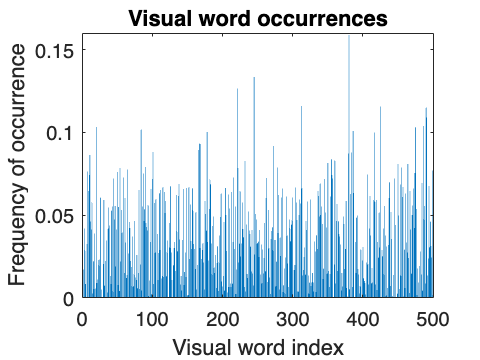


% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')


% Train an image category classifier using the bag of features
categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);

Training an image category classifier for 5 categories.
--------------------------------------------------------
* Category 1: butter_knife
* Category 2: cutting_knife
* Category 3: fork
* Category 4: ladle
* Category 5: spoon

* Encoding features for 55 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.




% Evaluate the classifier using the training set (as a sanity check)
confMatrixTrain = evaluate(categoryClassifier, trainingSet);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: butter_knife
* Category 2: cutting_knife
* Category 3: fork
* Category 4: ladle
* Category 5: spoon

* Evaluating 55 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                         PREDICTED
KNOWN            | butter_knife   cutting_knife   fork   ladle   spoon   
-------------------------------------------------------------------------
butter_knife     | 0.64           0.18            0.09   0.09    0.00    
cutting_knife    | 0.00           0.82            0.00   0.18    0.00    
fork             | 0.00           0.00            0.82   0.00    0.18    
ladle            | 0.00           0.00            0.00   1.00    0.00    
spoon            | 0.00           0.00            0.00   0.18    0.82    

* Average Accuracy is 0.82.



trainAccuracy = mean(diag(confMatrixTrain));

% Evaluate the classifier using the validation set
confMatrixValidation = evaluate(categoryClassifier, validationSet);

Evaluating image category classifier for 5 categories.
-------------------------------------------------------

* Category 1: butter_knife
* Category 2: cutting_knife
* Category 3: fork
* Category 4: ladle
* Category 5: spoon

* Evaluating 19 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                         PREDICTED
KNOWN            | butter_knife   cutting_knife   fork   ladle   spoon   
-------------------------------------------------------------------------
butter_knife     | 0.25           0.00            0.25   0.50    0.00    
cutting_knife    | 0.25           0.25            0.00   0.25    0.25    
fork             | 0.00           0.00            0.75   0.25    0.00    
ladle            | 0.00           0.00            0.00   1.00    0.00    
spoon            | 0.00           0.00            0.00   0.00    1.00    

* Average Accuracy is 0.65.



validationAccuracy = mean(diag(confMatrixValidation));

% Display the accuracies
fprintf('Training Accuracy: %.2f%%\n', trainAccuracy * 100);

Training Accuracy: 81.82%


fprintf('Validation Accuracy: %.2f%%\n', validationAccuracy * 100);

Validation Accuracy: 65.00%
